# SVM Regression with standard RBF kernel

## Random dataset with non linearly separable classes in $R^2$

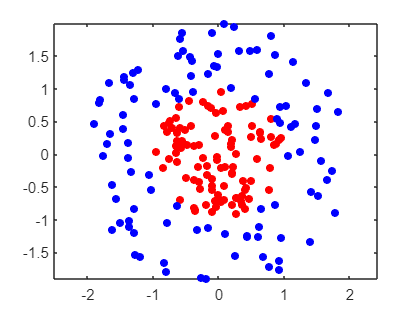

r = sqrt(rand(100 ,1));                         % random radius
t = 2*pi*rand(100 ,1);                          % random angle
data1 = [r.* cos(t), r.* sin(t)];               % points of class -1 (RED)

r2 = sqrt(3*rand(100 ,1) +1);                   % random radius for blue ring
t2 = 2* pi*rand (100,1);                        % random angle for blue ring
data2 = [r2 .* cos(t2), r2 .* sin(t2)];         % points of class +1 ( BLUE )
data3  = [data1; data2];                        % merge data together

figure
plot(data1(:,1), data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1), data2(:,2),'b.','MarkerSize',15)
axis equal
hold off

## Run Support Vector Regression

y = franke(data3(:,1), data3(:,2));
regSVM = fitrsvm (data3, y, 'KernelFunction','rbf', ...
             'BoxConstraint',10, 'Epsilon' ,0.05 , 'Standardize',true );

flag = regSVM.ConvergenceInfo.Converged         % check convergence

flag = logical
   1


num_supVec = numel (regSVM.Alpha)               % Number of support vectors 

num_supVec = 61

idx_supVec = regSVM.IsSupportVector ;           % logical array to identify support vectors

## Prediction on a grid

d = 0.2;
[x1Grid,x2Grid] = meshgrid(min(data3(:,1)):d:max(data3(:,1)),...
    min(data3(:,2)):d:max(data3(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];

response = predict(regSVM, xGrid);

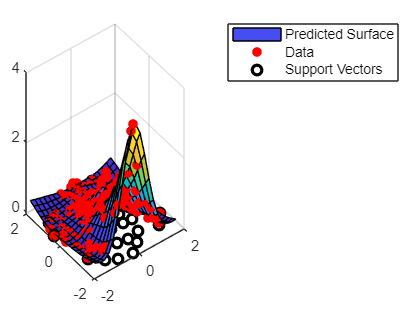

% Visualize 
figure
surf(x1Grid, x2Grid, reshape(response,size(x1Grid))  )
hold on
scatter3(data3(:,1), data3(:,2),y, 'r', 'filled')
supVec = data3(regSVM.IsSupportVector,:);
plot(supVec(:,1), supVec(:,2), 'ko', 'LineWidth',2)
legend("Predicted Surface", "Data", "Support Vectors")